# Тесты

Тест 1(n = 15)

format long;
n = 15;
H = hilb(n);
e = ones(n,1);
b = H*e;
x_lu = LU_solve(H,b);
x_qr = QR_solve(H,b);

Норма погрешностей:

norm(x_lu - e)

ans =   14.477418322101377


norm(x_qr - e)

ans =      1.515345701284949e+02


Исследование влияния параметра регуляризации:

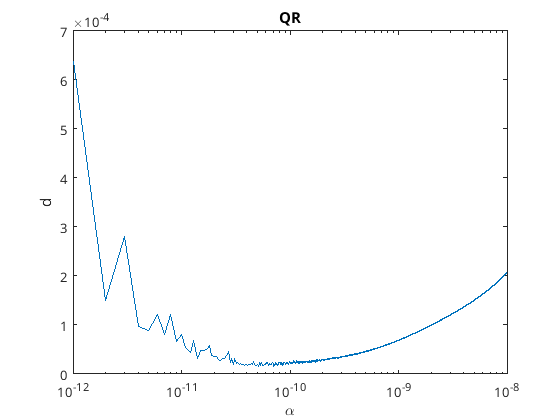

alpha = 1e-12;
E = eye(n);
d = zeros(1e4,1);
for i = 1:1e4
    A = H + alpha*i*E;
    x = QR_solve(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e4),d);
title('QR');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans =      5.100000000000000e-11


disp('Который равен:');

Который равен:


m

m =      1.557714868056843e-05


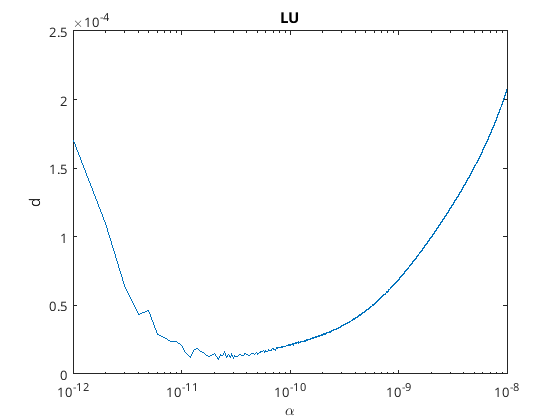

alpha = 1e-12;
E = eye(n);
d = zeros(1e4,1);
for i = 1:1e4
    A = H + alpha*i*E;
    x = LU_solve(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e4),d);
title('LU');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans =      2.200000000000000e-11


disp('Который равен:');

Который равен:


m

m =      1.033167731781375e-05


Тест 2(n = 20)

n = 20;
H = hilb(n);
e = ones(n,1);
b = H*e;
x_lu = LU_solve(H,b);
x_qr = QR_solve(H,b);

Норма погрешностей:

norm(x_lu - e)

ans =      1.276901113376399e+02


norm(x_qr - e)

ans =      4.329126736148064e+02


Исследование влияния параметра регуляризации:

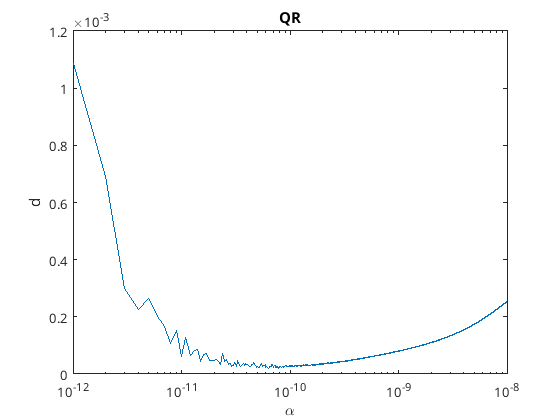

alpha = 1e-12;
E = eye(n);
d = zeros(1e4,1);
for i = 1:1e4
    A = H + alpha*i*E;
    x = QR_solve(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e4),d);
title('QR');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans =      6.300000000000000e-11


disp('Который равен:');

Который равен:


m

m =      2.022569013333741e-05


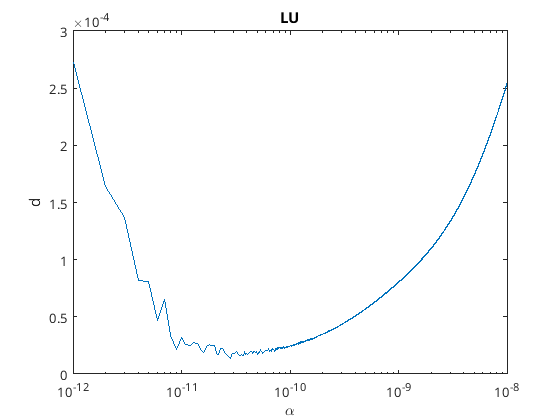

alpha = 1e-12;
E = eye(n);
d = zeros(1e4,1);
for i = 1:1e4
    A = H + alpha*i*E;
    x = LU_solve(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e4),d);
title('LU');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans =      2.800000000000000e-11


disp('Который равен:');

Который равен:


m

m =      1.363301345515417e-05


Тест 3(n = 25)

n = 25;
H = hilb(n);
e = ones(n,1);
b = H*e;
x_lu = LU_solve(H,b);
x_qr = QR_solve(H,b);

Норма погрешностей:

norm(x_lu - e)

ans =      6.454667338562547e+02


norm(x_qr - e)

ans =      4.567302536131110e+02


Исследование влияния параметра регуляризации:

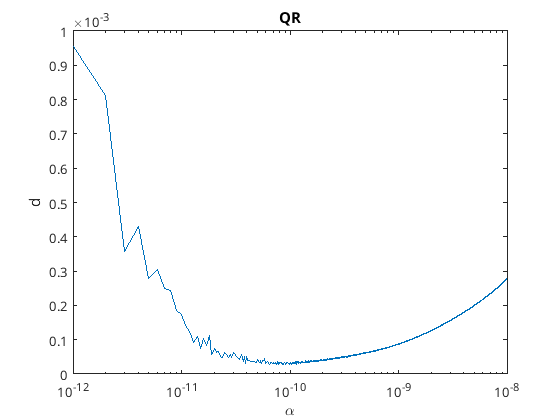

alpha = 1e-12;
E = eye(n);
d = zeros(1e4,1);
for i = 1:1e4
    A = H + alpha*i*E;
    x = QR_solve(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e4),d);
title('QR');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans =      7.900000000000000e-11


disp('Который равен:');

Который равен:


m

m =      2.630347261279233e-05


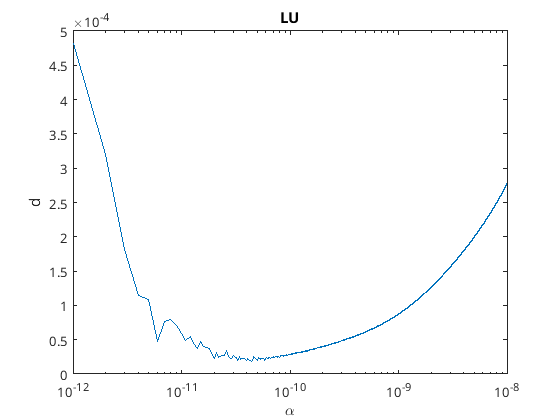

alpha = 1e-12;
E = eye(n);
d = zeros(1e4,1);
for i = 1:1e4
    A = H + alpha*i*E;
    x = LU_solve(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e4),d);
title('LU');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans =      4.400000000000000e-11


disp('Который равен:');

Который равен:


m

m =      1.856914958199387e-05


[l_1,u_1] = LU(H);